data = load('resultadosCSV_magic.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

clf;
fig = figure;
bordes      = -0.5:1:400.5;
h1           = histogram(stop, bordes); title('Stop'); xlabel('bin'); ylabel('Frequency');
h1.EdgeColor = 'none'

h1 =   Histogram with properties:

             Data: [10240×1 double]
           Values: [1×401 double]
          NumBins: 401
         BinEdges: [1×402 double]
         BinWidth: 1
        BinLimits: [-0.5000 400.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


bines_stop  = h1.BinCounts;
% saveas(gcf,'histograma_stop.eps', 'eps');
exportgraphics(fig,'histograma_stop.eps')

maxbin_stop = max(find(bines_stop, 1, 'last'))-1

maxbin_stop = 352

minbin_stop = min(find(bines_stop, 1, 'first'))-1

minbin_stop = 34

Nc_stop     = maxbin_stop - minbin_stop

Nc_stop = 318



T   = 5e-9;
tau = T/Nc_stop

tau = 1.5723e-11

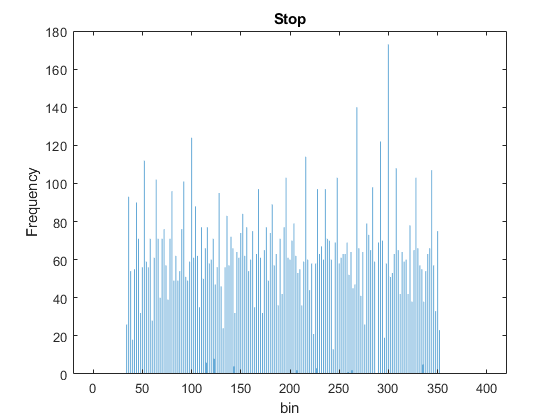


%%Real

N           = length(stop);    %numero de ensayos

t = tiledlayout(3,1);

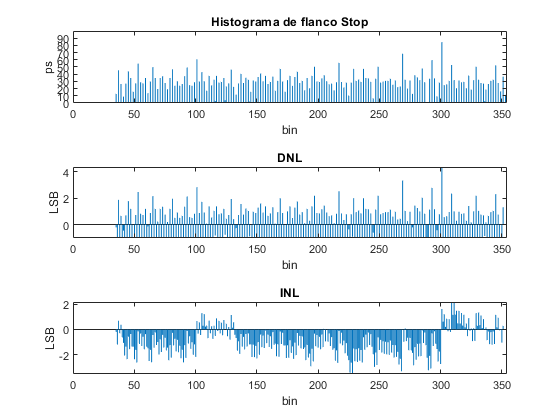

%Histograma
nexttile;
t_i         = bines_stop*(T/N);
bar(t_i(1, 1:353)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Stop');
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70 80 90]*1e-12)
yticklabels({0 10 20 30 40 50 60 70 80 90})

%DNL
nexttile;
dnl_i = (t_i - tau)/tau;
dnl_i(1, 1:minbin_stop) = 0;
dnl_i(1, maxbin_stop:end) = 0;
bar(dnl_i(1, 1:353)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_i = cumsum(dnl_i);
inl_i(1, maxbin_stop:end) = 0;
bar(inl_i(1:353)); ylabel('LSB'); xlabel('bin'); title('INL')

inl_stop = inl_i;
exportgraphics(t,'linealidad_stop.eps')

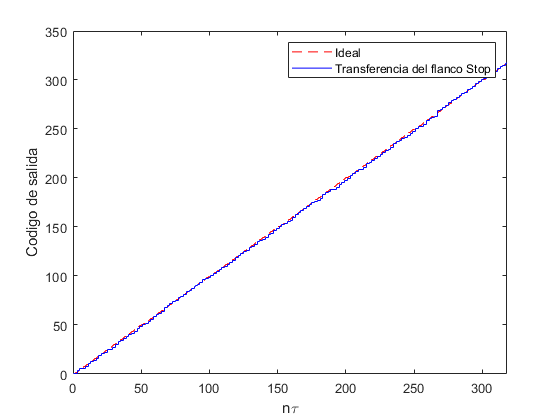

% saveas(gcf,'linealidad_stop.eps', 'eps');

clf;
% x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
format short
x_tiempo = 0:319-1;
y_ideal  = 0:length(x_tiempo)-1;
y_real = inl_i(1, minbin_stop:maxbin_stop) + y_ideal;
% plot(x_tiempo, y_ideal, x_tiempo, y_real);
stairs(x_tiempo, y_ideal, 'r--');
hold on;
stairs(x_tiempo, y_real, 'b')
hold off;
xlabel('n\tau'); ylabel('Codigo de salida');
legend('Ideal', 'Transferencia del flanco Stop');
ax = gca; 
ax.XLim = [0, max(x_tiempo)];
% saveas(gcf,'transferencia_stop.eps', 'eps');
exportgraphics(gcf,'transferencia_stop.eps')

clf;
fig = figure();
bordes      = -0.5:1:400.5;
h           = histogram(start, bordes); title('Start'); xlabel('bin'); ylabel('Frequency');
h.EdgeColor = 'none'

h =   Histogram with properties:

             Data: [10240×1 double]
           Values: [1×401 double]
          NumBins: 401
         BinEdges: [1×402 double]
         BinWidth: 1
        BinLimits: [-0.5000 400.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


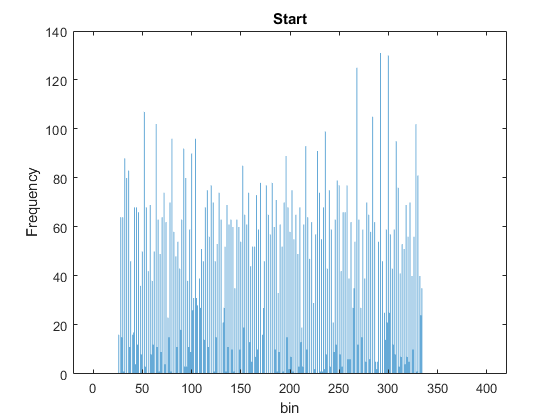

bines_start = h.BinCounts;
exportgraphics(fig,'histograma_start.eps');

% export_fig('prueba','-eps', '-r600');

maxbin_start = max(find(bines_start, 1, 'last'))

maxbin_start = 335

minbin_start = min(find(bines_start, 1, 'first'))

minbin_start = 27

Nc_start     = maxbin_start - minbin_start

Nc_start = 308


%%Ideal
T   = 5e-9;
tau_start = T/Nc_start

tau_start = 1.6234e-11


%%Real
clf;
N           = length(start);    %numero de ensayos

t_start = tiledlayout(3,1)

t_start =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


%Histograma
nexttile;
t_i         = bines_start*(T/N);
bar(t_i(1, 1:353)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Start')
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70]*1e-12)
yticklabels({0 10 20 30 40 50 60 70})

%DNL
nexttile;
dnl_i = (t_i - tau)/tau;
dnl_i(1, 1:minbin_start) = 0;
dnl_i(1, maxbin_start:end) = 0;
bar(dnl_i(1, 1:353)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_i = cumsum(dnl_i)

inl_i =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -1.0000   -0.0125   -0.5467    0.4408   -0.5281    1.2047    0.2047    1.6891    0.6891    2.2666    1.6082    2.0367    1.0367    0.5336    0.0615    1.1732    0.2975    1.4092    0.7818    1.8314    0.8314    0.9494    0.1979


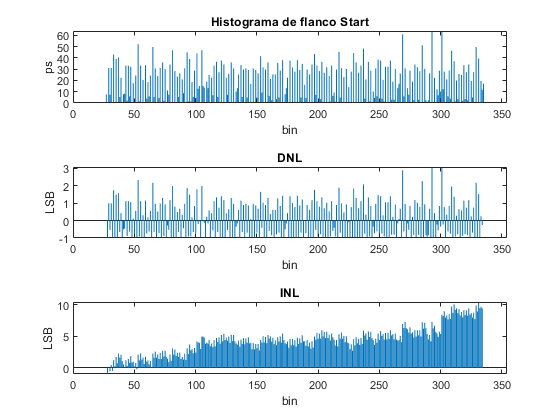

inl_i(1, maxbin_start:end) = 0;
bar(inl_i(1:353)); ylabel('LSB'); xlabel('bin'); title('INL')

inl_start = inl_i;
exportgraphics(t_start,'linealidad_start.eps');

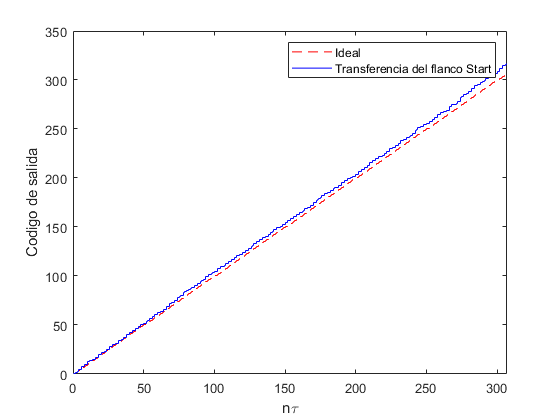


clf;
% x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
format short
x_tiempo = 0:Nc_start-1;
y_ideal  = 0:length(x_tiempo)-1;
y_real = inl_i(1, minbin_start:maxbin_start-1)+y_ideal;
% plot(x_tiempo, y_ideal, x_tiempo, y_real);
stairs(x_tiempo, y_ideal, 'r--');
hold on;
stairs(x_tiempo, y_real, 'b')
hold off;
xlabel('n\tau'); ylabel('Codigo de salida');
legend('Ideal', 'Transferencia del flanco Start');
ax = gca; 
ax.XLim = [0, max(x_tiempo)];
exportgraphics(gcf,'transferencia_start.eps');